# Converting Between Color Spaces

Now that you've been introduced to different color spaces, let's practice converting between them. This is a first step to thresholding color images or adjusting the contrast of color images, which you will learn about later in this course. Work through this script section by section to practice converting an image from RGB to alternative color spaces and back to RGB.

### Import and display a color image

Run this section to read in an image of an ice shelf and display it.

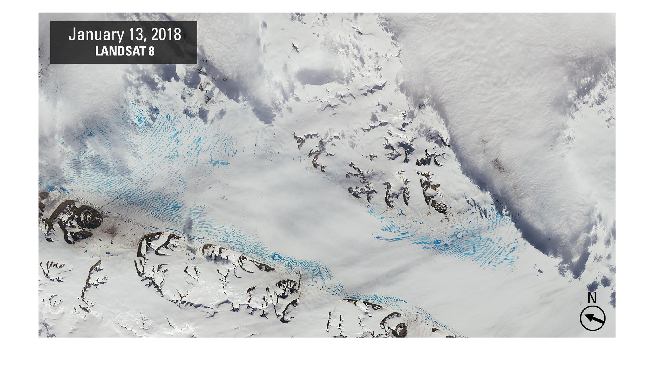

img = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
imshow(img)

### Convert to alternative color spaces

Uncomment the lines of code below and convert the image to alternative color spaces. Use the variable names provided as they will be used in the rest of this script.

Convert to HSV

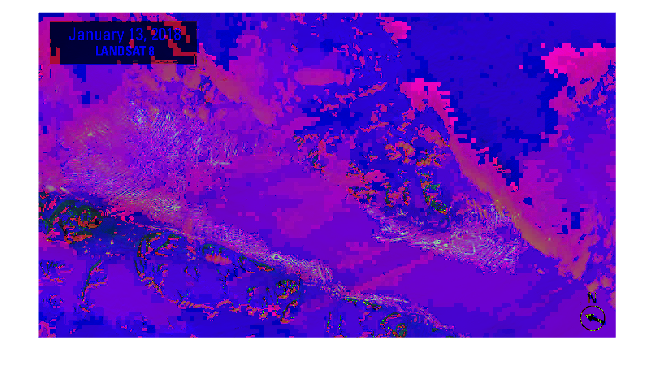

hsvImg = rgb2hsv(img);
imshow(hsvImg)

rgbImg = hsv2rgb(hsvImg);
imshow(rgbImg)

Convert to YCbCr

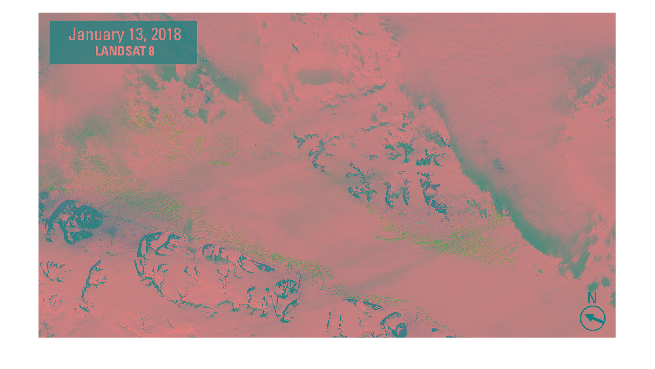

ycbcrImg = rgb2ycbcr(img);
imshow(ycbcrImg)

Convert to L*a*b*

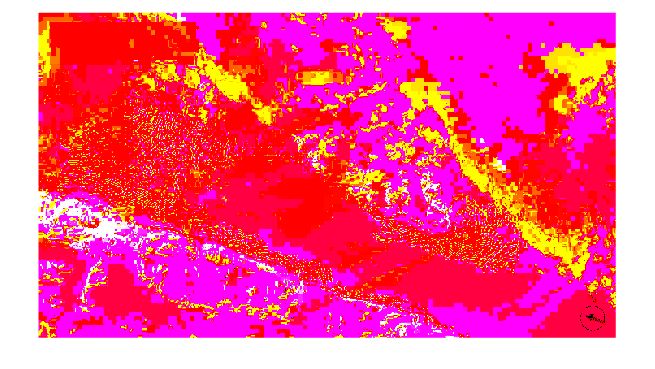

labImg = rgb2lab(img);
imshow(labImg)

### Examine the matrix values and data types

The code below extracts the values at the top left hand corner of the third color plane for all four images. Examine the results. 

img(1:10,1:10,3)

ans = 10×10 uint8 matrix
   184   183   181   179   178   178   180   178   177   182
   183   182   180   179   178   178   179   178   178   181
   183   182   180   178   177   177   179   179   178   179
   182   181   179   177   176   176   177   179   180   179
   181   180   178   176   176   176   176   177   180   177
   181   179   177   176   175   175   175   177   178   174
   180   179   176   175   174   174   174   176   176   172
   181   178   175   175   174   174   174   176   177   172
   183   177   174   176   176   173   174   177   178   174
   180   176   174   179   179   175   174   177   175   173


hsvImg(1:10,1:10,3)

ans =     0.7216    0.7176    0.7098    0.7020    0.6980    0.6980    0.7059    0.6980    0.6941    0.7137
    0.7176    0.7137    0.7059    0.7020    0.6980    0.6980    0.7020    0.6980    0.6980    0.7098
    0.7176    0.7137    0.7059    0.6980    0.6941    0.6941    0.7020    0.7020    0.6980    0.7020
    0.7137    0.7098    0.7020    0.6941    0.6902    0.6902    0.6941    0.7020    0.7059    0.7020
    0.7098    0.7059    0.6980    0.6902    0.6902    0.6902    0.6902    0.6941    0.7059    0.6941
    0.7098    0.7020    0.6941    0.6902    0.6863    0.6863    0.6863    0.6941    0.6980    0.6824
    0.7059    0.7020    0.6902    0.6863    0.6824    0.6824    0.6824    0.6902    0.6902    0.6745
    0.7098    0.6980    0.6863    0.6863    0.6824    0.6824    0.6824    0.6902    0.6941    0.6745
    0.7176    0.6941    0.6824    0.6902    0.6902    0.6784    0.6824    0.6941    0.6980    0.6824
    0.7059    0.6902    0.6824    0.7020    0.7020    0.6863    0.6824    0.6941    0

ycbcrImg(1:10,1:10,3)

ans = 10×10 uint8 matrix
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128


labImg(1:10,1:10,3)

ans = 1.0e-13 *

         0         0         0         0         0         0   -0.2220         0         0   -0.2220
         0   -0.2220   -0.2220         0         0         0         0         0         0         0
         0   -0.2220   -0.2220         0         0         0         0         0         0         0
   -0.2220         0         0         0         0         0         0         0   -0.2220         0
         0   -0.2220         0         0         0         0         0         0   -0.2220         0
         0         0         0         0         0         0         0         0         0         0
   -0.2220         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
   -0.2220         0         0         0         0         0         0    

rgbImg(1:10,1:10,3)

ans =     0.7216    0.7176    0.7098    0.7020    0.6980    0.6980    0.7059    0.6980    0.6941    0.7137
    0.7176    0.7137    0.7059    0.7020    0.6980    0.6980    0.7020    0.6980    0.6980    0.7098
    0.7176    0.7137    0.7059    0.6980    0.6941    0.6941    0.7020    0.7020    0.6980    0.7020
    0.7137    0.7098    0.7020    0.6941    0.6902    0.6902    0.6941    0.7020    0.7059    0.7020
    0.7098    0.7059    0.6980    0.6902    0.6902    0.6902    0.6902    0.6941    0.7059    0.6941
    0.7098    0.7020    0.6941    0.6902    0.6863    0.6863    0.6863    0.6941    0.6980    0.6824
    0.7059    0.7020    0.6902    0.6863    0.6824    0.6824    0.6824    0.6902    0.6902    0.6745
    0.7098    0.6980    0.6863    0.6863    0.6824    0.6824    0.6824    0.6902    0.6941    0.6745
    0.7176    0.6941    0.6824    0.6902    0.6902    0.6784    0.6824    0.6941    0.6980    0.6824
    0.7059    0.6902    0.6824    0.7020    0.7020    0.6863    0.6824    0.6941    0

The results look completely different! Also, take a look at the workspace to see the different data types of the matrices. 

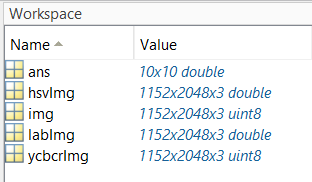

Notice how the original image and the YCbCr representation are both of type uint8, but the HSV and L*a*b* values are of type double. This is important to remember as you perform your own color space conversions.

### Display the converted images

Finally, show all the converted images just to make sure they still look the same.

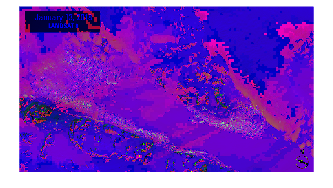

imshow(hsvImg)

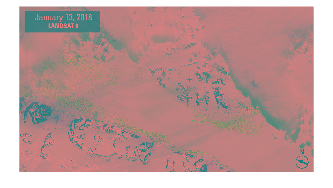

imshow(ycbcrImg)

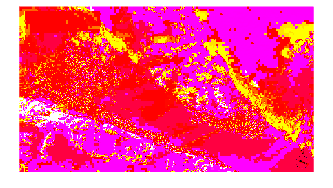

imshow(labImg)

Oh no! This doesn't look right! What happened?

### Display the image correctly in RGB

The `imshow` function only interprets images in the RGB color space. It does, however, accept matrices of different data types, including both uint8 and double, which is why we were able to run `imshow` with the HSV and L*a*b* images. 

*Always convert back to RGB* when working with images in different color spaces before displaying them.

Uncomment the lines below to convert the images back to RGB.

Convert from HSV to RGB

rgbImg1 = hsv2rgb(hsvImg)

rgbImg1 = rgbImg1(:,:,1) =

    0.7216    0.7176    0.7098    0.7020    0.6980    0.6980    0.7059    0.6980    0.6941    0.7137    0.7216    0.7137    0.7020    0.6902    0.6902    0.6980    0.7020    0.7059    0.7020    0.6941    0.6941    0.6902    0.6902    0.6824    0.6863    0.6941    0.6980    0.7020    0.7059    0.7059    0.7020    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6941    0.6863    0.6863    0.6863    0.6863    0.6902    0.6980    0.6980    0.6824    0.6863    0.6941    0.6980    0.7020    0.7020    0.7020    0.6902    0.6824    0.6863    0.6863    0.6902    0.6941    0.6941    0.7020    0.6980    0.6980    0.6980    0.6902    0.6863    0.6863    0.6824    0.6824    0.6824    0.6824    0.6863    0.6902    0.6902    0.6941    0.6941    0.7020    0.7059    0.7059    0.7059    0.7020    0.7020    0.6980    0.6980    0.6980    0.6980    0.7059    0.7059    0.7020    0.6980    0.6941    0.6863    0.6902    0.6863    0.6902    0.6902    0.6941  

Convert from YCbCr to RGB

rgbImg2 = ycbcr2rgb(ycbcrImg) 

rgbImg2 = 1152×2048×3 uint8 array
rgbImg2(:,:,1) =

   184   183   180   179   178   178   180   178   177   182   184   182   179   176   176   178   179   180   179   177   177   176   176   173   175   177   178   179   180   180   179   178   178   178   178   178   178   178   177   175   175   175   175   176   178   178   173   175   177   178   179   179   179   176   173   175   175   176   177   177   179   178   178   178   176   175   175   173   173   173   173   175   176   176   177   177   179   180   180   180   179   179   178   178   178   178   180   180   179   178   177   175   176   175   176   176   177   177   177   177   175   175   176   177   178   179   179   182   179   179   178   178   177   178   177   177   175   174   172   172   172   174   177   180   181   182   184   184   184   184   181   180   184   186   186   187   187   187   186   187   186   186   186   186   186   186   186   187   188   188   189   188   188   188   192   192   188   188

Convert from L*a*b* to RGB

rgbImg3 = lab2rgb(labImg)

rgbImg3 = rgbImg3(:,:,1) =

    0.7216    0.7176    0.7098    0.7020    0.6980    0.6980    0.7059    0.6980    0.6941    0.7137    0.7216    0.7137    0.7020    0.6902    0.6902    0.6980    0.7020    0.7059    0.7020    0.6941    0.6941    0.6902    0.6902    0.6824    0.6863    0.6941    0.6980    0.7020    0.7059    0.7059    0.7020    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6941    0.6863    0.6863    0.6863    0.6863    0.6902    0.6980    0.6980    0.6824    0.6863    0.6941    0.6980    0.7020    0.7020    0.7020    0.6902    0.6824    0.6863    0.6863    0.6902    0.6941    0.6941    0.7020    0.6980    0.6980    0.6980    0.6902    0.6863    0.6863    0.6824    0.6824    0.6824    0.6824    0.6863    0.6902    0.6902    0.6941    0.6941    0.7020    0.7059    0.7059    0.7059    0.7020    0.7020    0.6980    0.6980    0.6980    0.6980    0.7059    0.7059    0.7020    0.6980    0.6941    0.6863    0.6902    0.6863    0.6902    0.6902    0.6941  

Display the images again.

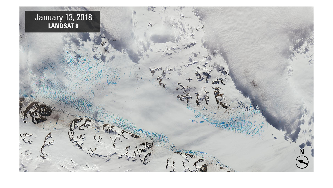

imshow(rgbImg1)

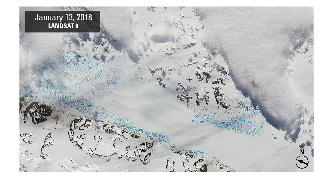

imshow(rgbImg2)

imshow(rgbImg3)

That's much better! All of these images look identical to the original image. Do note that changing the images back to RGB does not change their datatypes, so two of the three new RGB images are of type double. 

*Copyright 2022 The MathWorks, Inc.*